# Assignment 4 Machine Learning SYED MUHAMMAD ZAIN REGNO:329876 

clc
clear all

Data=load('E:\NUST\Semester 2\machine learning\assignment 4\MNIST\mnist_train.csv')

Data =      5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0

## Preprocessing of the mnist dataset to 100x784 form

%checking size of original data
size(Data); % size 60000x785 originally
sortedD=sortrows(Data,1);
%extracting 10 images of each label to maintain uniformity
zero=sortedD(1:10,:);
one=sortedD(5924:5933,:);
two=sortedD(12666:12675,:);
three=sortedD(18704:18713,:);
four=sortedD(25675:25684,:);
five=sortedD(31940:31949,:);
six=sortedD(37609:37618,:);
seven=sortedD(42385:42394,:);
eight=sortedD(48950:48959,:);
nine=sortedD(54920:54929,:);

%This is final 
FinalD=[zero;one;two;three;four;five;six;seven;eight;nine];
%extracting labels and images 
images1=FinalD(:,2:785);
labels=FinalD(:,1);
images1=double(images1);
images1=images1./255;
size(labels);%final formated label size 100x1
size(images1) %final formatted images 100x784

ans =    100   784


## PCA 

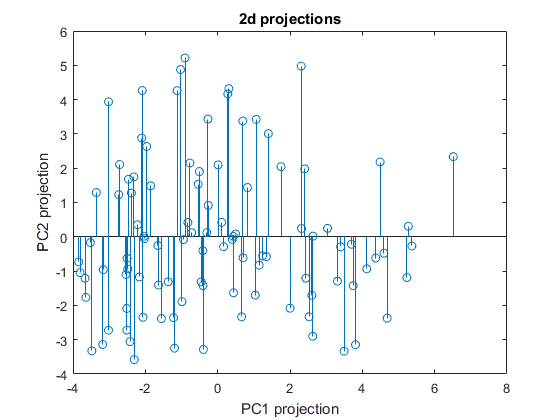

X=images1;
nd=2;
Xmean=repmat(mean(X),size(X,1),1);
X=X-Xmean;
%step 3, covariance matrix
covariancematrix=cov(X);
%step 4, Finding Eigenvectors
[u, v, d] = svd(covariancematrix);
u=u(:,1:nd); %column-wise principal components
%step 5, Deriving the new data set
%finding the projection onto the eigenvectors
Xnew=X*u; %[N x d] x [d x nd] = [N x nd] matrix
%size of Xnew
stem(Xnew(:,1),Xnew(:,2))
title('2d projections')
xlabel('PC1 projection')
ylabel('PC2 projection')

## LDA

[Xnew1]=LDA(images1,labels);
size(Xnew1)

ans =    100     2


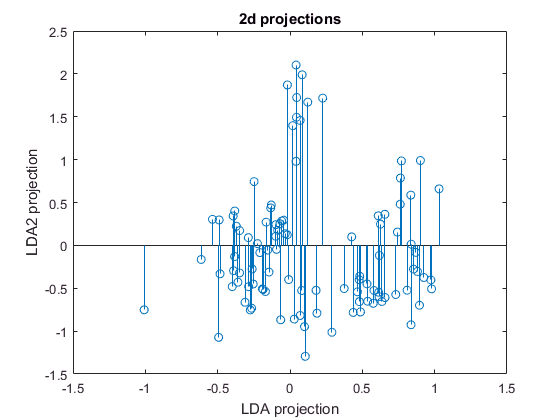

stem(Xnew1(:,1),Xnew1(:,2))
title('2d projections')
xlabel('LDA projection')
ylabel('LDA2 projection')

## NCA

[mappedX, mapping] = nca(images1, labels, 2, 0);

Iteration 1 of 3...


Iteration 2 of 3...


Iteration 3 of 3...


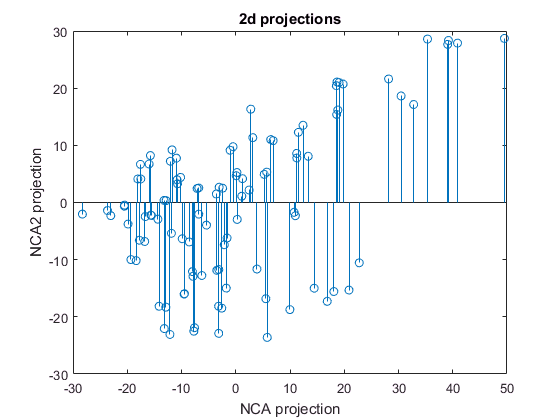

stem(mappedX(:,1),mappedX(:,2))
title('2d projections')
xlabel('NCA projection')
ylabel('NCA2 projection')

## Scatterplots

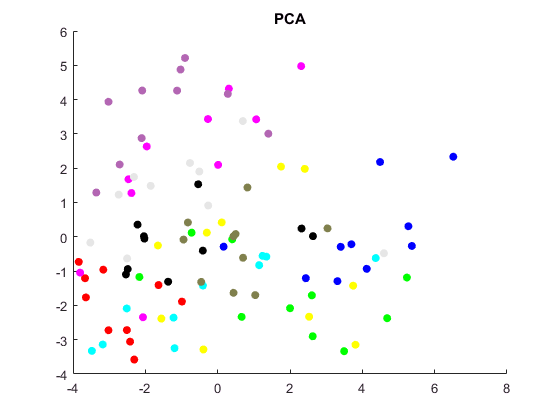

%plotting PCA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew(1:10,:);
XnewP2=Xnew(11:20,:);
XnewP3=Xnew(21:30,:);
XnewP4=Xnew(31:40,:);
XnewP5=Xnew(41:50,:);
XnewP6=Xnew(51:60,:);
XnewP7=Xnew(61:70,:);
XnewP8=Xnew(71:80,:);
XnewP9=Xnew(81:90,:);
XnewP10=Xnew(91:100,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('PCA')
hold off

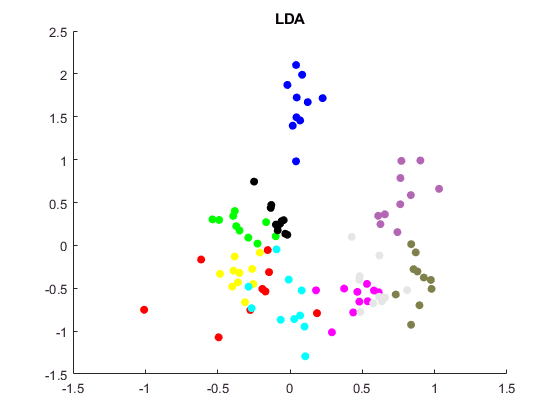

%plotting LDA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew1(1:10,:);
XnewP2=Xnew1(11:20,:);
XnewP3=Xnew1(21:30,:);
XnewP4=Xnew1(31:40,:);
XnewP5=Xnew1(41:50,:);
XnewP6=Xnew1(51:60,:);
XnewP7=Xnew1(61:70,:);
XnewP8=Xnew1(71:80,:);
XnewP9=Xnew1(81:90,:);
XnewP10=Xnew1(91:100,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('LDA')
hold off

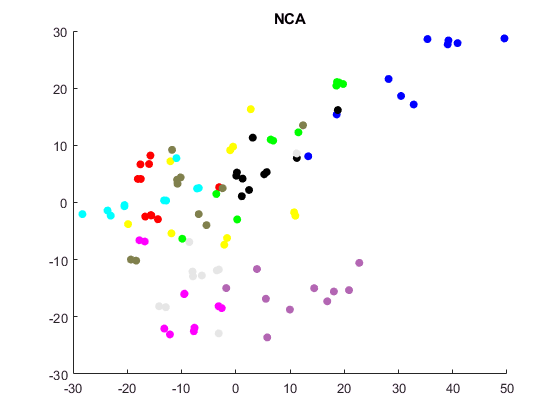

%plotting NCA
color1=[0,0.4470, 0.7410];
XnewP1=mappedX(1:10,:);
XnewP2=mappedX(11:20,:);
XnewP3=mappedX(21:30,:);
XnewP4=mappedX(31:40,:);
XnewP5=mappedX(41:50,:);
XnewP6=mappedX(51:60,:);
XnewP7=mappedX(61:70,:);
XnewP8=mappedX(71:80,:);
XnewP9=mappedX(81:90,:);
XnewP10=mappedX(91:100,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('NCA')
hold off

## 20 Samples  case

## Preprocessing of the mnist dataset to 200x784 form

%checking size of original data
size(Data); % size 60000x785 originally
sortedD=sortrows(Data,1);
%extracting 10 images of each label to maintain uniformity
zero=sortedD(1:20,:);
one=sortedD(5924:5943,:);
two=sortedD(12666:12685,:);
three=sortedD(18704:18723,:);
four=sortedD(25675:25694,:);
five=sortedD(31940:31959,:);
six=sortedD(37609:37628,:);
seven=sortedD(42385:42404,:);
eight=sortedD(48950:48969,:);
nine=sortedD(54920:54939,:);

%This is final 
FinalD=[zero;one;two;three;four;five;six;seven;eight;nine];
%extracting labels and images 
images2=FinalD(:,2:785);
labels2=FinalD(:,1);
images2=double(images2);
images2=images2./255;
size(labels2);%final formated label size 200x1
size(images2) %final formatted images 200x784

ans =    200   784


## PCA 

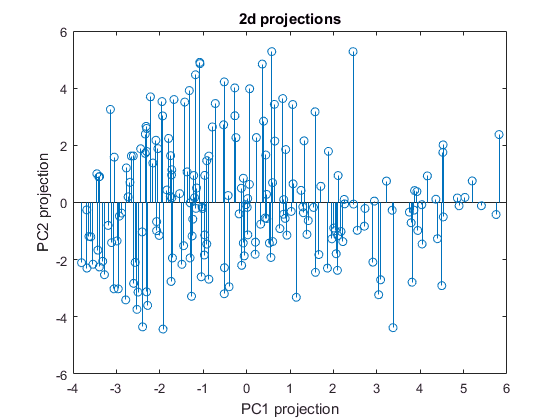

X=images2;
nd=2;
Xmean=repmat(mean(X),size(X,1),1);
X=X-Xmean;
%step 3, covariance matrix
covariancematrix=cov(X);
%step 4, Finding Eigenvectors
[u, v, d] = svd(covariancematrix);
u=u(:,1:nd); %column-wise principal components
%step 5, Deriving the new data set
%finding the projection onto the eigenvectors
Xnew3=X*u; %[N x d] x [d x nd] = [N x nd] matrix
%size of Xnew
stem(Xnew3(:,1),Xnew3(:,2))
title('2d projections')
xlabel('PC1 projection')
ylabel('PC2 projection')

## LDA

[Xnew4]=LDA(images2,labels2);
size(Xnew4)

ans =    200     2


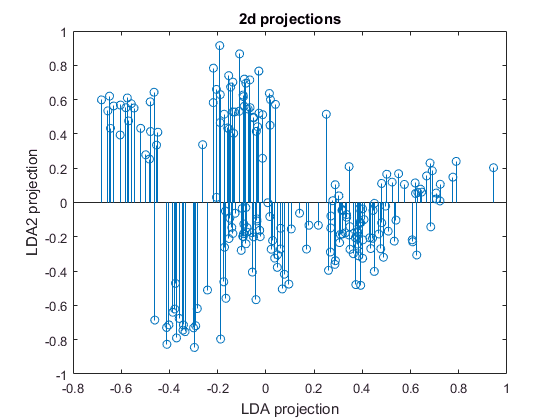

stem(Xnew4(:,1),Xnew4(:,2))
title('2d projections')
xlabel('LDA projection')
ylabel('LDA2 projection')

## NCA

[Xnew5, mapping] = nca(images2, labels2, 2, 0);

Iteration 1 of 3...


Iteration 2 of 3...


Iteration 3 of 3...


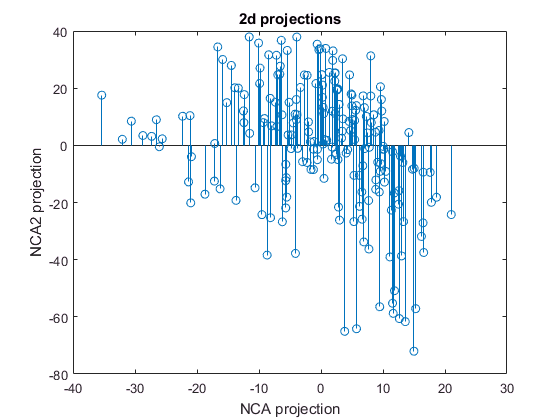

stem(Xnew5(:,1),Xnew5(:,2))
title('2d projections')
xlabel('NCA projection')
ylabel('NCA2 projection')

## Scatterplots

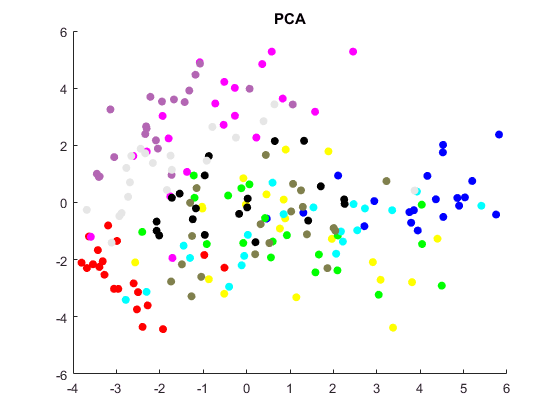

%plotting PCA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew3(1:20,:);
XnewP2=Xnew3(21:40,:);
XnewP3=Xnew3(41:60,:);
XnewP4=Xnew3(61:80,:);
XnewP5=Xnew3(81:100,:);
XnewP6=Xnew3(101:120,:);
XnewP7=Xnew3(121:140,:);
XnewP8=Xnew3(141:160,:);
XnewP9=Xnew3(161:180,:);
XnewP10=Xnew3(181:200,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('PCA')
hold off

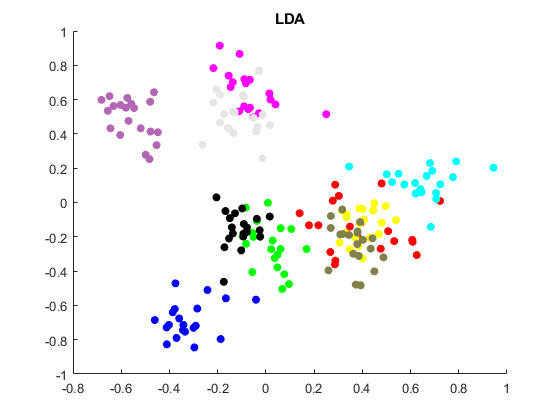

%plotting LDA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew4(1:20,:);
XnewP2=Xnew4(21:40,:);
XnewP3=Xnew4(41:60,:);
XnewP4=Xnew4(61:80,:);
XnewP5=Xnew4(81:100,:);
XnewP6=Xnew4(101:120,:);
XnewP7=Xnew4(121:140,:);
XnewP8=Xnew4(141:160,:);
XnewP9=Xnew4(161:180,:);
XnewP10=Xnew4(181:200,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('LDA')
hold off

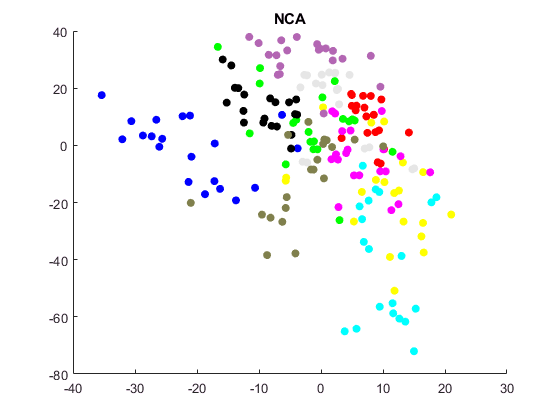

%plotting NCA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew5(1:20,:);
XnewP2=Xnew5(21:40,:);
XnewP3=Xnew5(41:60,:);
XnewP4=Xnew5(61:80,:);
XnewP5=Xnew5(81:100,:);
XnewP6=Xnew5(101:120,:);
XnewP7=Xnew5(121:140,:);
XnewP8=Xnew5(141:160,:);
XnewP9=Xnew5(161:180,:);
XnewP10=Xnew5(181:200,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('NCA')
hold off

## Preprocessing of the mnist dataset to 500x784 form

%100 samples
%checking size of original data
size(Data); % size 60000x785 originally
sortedD=sortrows(Data,1);
%extracting 10 images of each label to maintain uniformity
zero=sortedD(1:50,:);
one=sortedD(5924:5973,:);
two=sortedD(12666:12715,:);
three=sortedD(18704:18753,:);
four=sortedD(25675:25724,:);
five=sortedD(31940:31989,:);
six=sortedD(37609:37658,:);
seven=sortedD(42385:42434,:);
eight=sortedD(48950:48999,:);
nine=sortedD(54920:54969,:);

%This is final 
FinalD=[zero;one;two;three;four;five;six;seven;eight;nine];
%extracting labels and images 
images3=FinalD(:,2:785);
labels3=FinalD(:,1);
images3=double(images3);
images3=images3./255;
size(labels3);%final formated label size 500x1
size(images3) %final formatted images 500x784

ans =    500   784


## PCA 

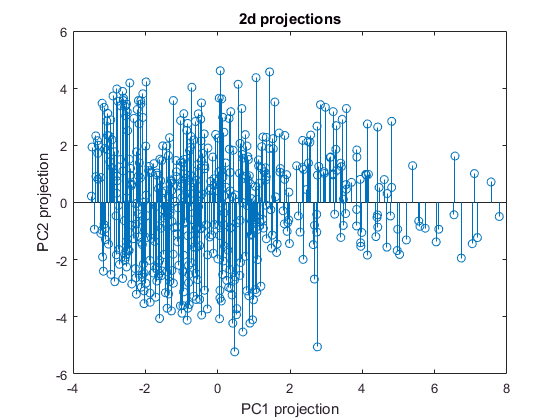

X=images3;
nd=2;
Xmean=repmat(mean(X),size(X,1),1);
X=X-Xmean;
%step 3, covariance matrix
covariancematrix=cov(X);
%step 4, Finding Eigenvectors
[u, v, d] = svd(covariancematrix);
u=u(:,1:nd); %column-wise principal components
%step 5, Deriving the new data set
%finding the projection onto the eigenvectors
Xnew6=X*u; %[N x d] x [d x nd] = [N x nd] matrix
%size of Xnew
stem(Xnew6(:,1),Xnew6(:,2))
title('2d projections')
xlabel('PC1 projection')
ylabel('PC2 projection')

## LDA

[Xnew7]=LDA(images3,labels3);
size(Xnew7)

ans =    500     2


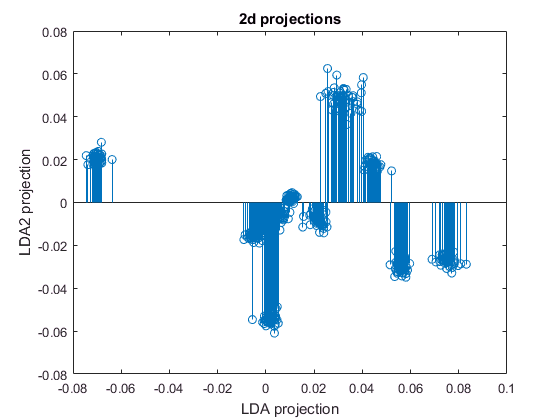

stem(Xnew7(:,1),Xnew7(:,2))
title('2d projections')
xlabel('LDA projection')
ylabel('LDA2 projection')

## NCA

[Xnew8, mapping] = nca(images3, labels3, 2, 0);

Iteration 1 of 3...


Iteration 2 of 3...


Iteration 3 of 3...


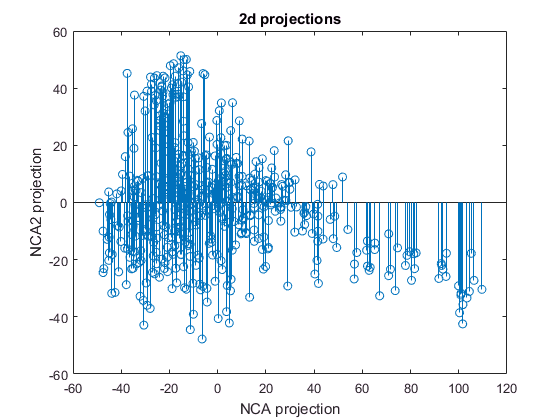

stem(Xnew8(:,1),Xnew8(:,2))
title('2d projections')
xlabel('NCA projection')
ylabel('NCA2 projection')

## Scatterplots

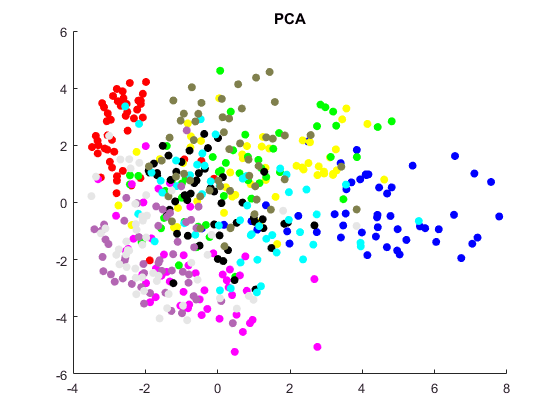

%plotting PCA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew6(1:50,:);
XnewP2=Xnew6(51:100,:);
XnewP3=Xnew6(101:150,:);
XnewP4=Xnew6(151:200,:);
XnewP5=Xnew6(201:250,:);
XnewP6=Xnew6(251:300,:);
XnewP7=Xnew6(301:350,:);
XnewP8=Xnew6(351:400,:);
XnewP9=Xnew6(401:450,:);
XnewP10=Xnew6(451:500,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('PCA')
hold off

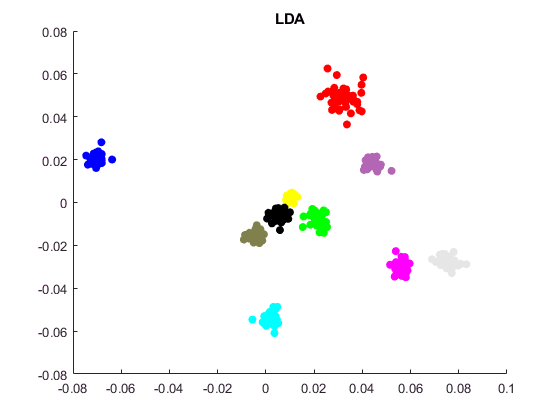

%plotting LDA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew7(1:50,:);
XnewP2=Xnew7(51:100,:);
XnewP3=Xnew7(101:150,:);
XnewP4=Xnew7(151:200,:);
XnewP5=Xnew7(201:250,:);
XnewP6=Xnew7(251:300,:);
XnewP7=Xnew7(301:350,:);
XnewP8=Xnew7(351:400,:);
XnewP9=Xnew7(401:450,:);
XnewP10=Xnew7(451:500,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('LDA')
hold off

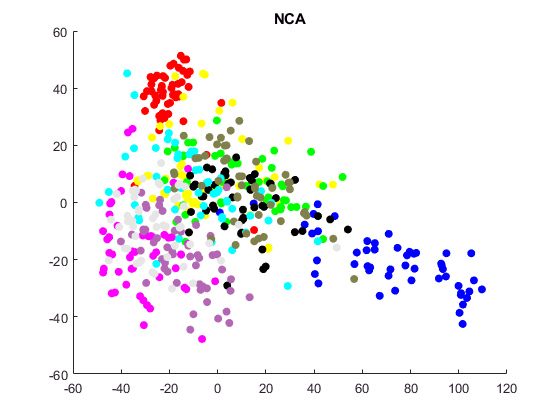

%plotting NCA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew8(1:50,:);
XnewP2=Xnew8(51:100,:);
XnewP3=Xnew8(101:150,:);
XnewP4=Xnew8(151:200,:);
XnewP5=Xnew8(201:250,:);
XnewP6=Xnew8(251:300,:);
XnewP7=Xnew8(301:350,:);
XnewP8=Xnew8(351:400,:);
XnewP9=Xnew8(401:450,:);
XnewP10=Xnew8(451:500,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('NCA')
hold off

## Preprocessing of the mnist dataset to 1000x784 form

%100 samples
%checking size of original data
size(Data); % size 60000x785 originally
sortedD=sortrows(Data,1);
%extracting 10 images of each label to maintain uniformity
zero=sortedD(1:100,:);
one=sortedD(5924:6023,:);
two=sortedD(12666:12765,:);
three=sortedD(18704:18803,:);
four=sortedD(25675:25774,:);
five=sortedD(31940:32039,:);
six=sortedD(37609:37708,:);
seven=sortedD(42385:42484,:);
eight=sortedD(48950:49049,:);
nine=sortedD(54920:55019,:);

%This is final 
FinalD=[zero;one;two;three;four;five;six;seven;eight;nine];
%extracting labels and images 
images4=FinalD(:,2:785);
labels4=FinalD(:,1);
images4=double(images4);
images4=images4./255;
size(labels4);%final formated label size 1000x1
size(images4) %final formatted images 100x784

ans =         1000         784


## PCA 

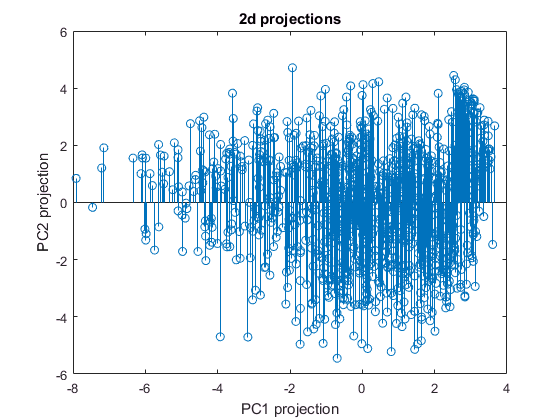

X=images4;
nd=2;
Xmean=repmat(mean(X),size(X,1),1);
X=X-Xmean;
%step 3, covariance matrix
covariancematrix=cov(X);
%step 4, Finding Eigenvectors
[u, v, d] = svd(covariancematrix);
u=u(:,1:nd); %column-wise principal components
%step 5, Deriving the new data set
%finding the projection onto the eigenvectors
Xnew9=X*u; %[N x d] x [d x nd] = [N x nd] matrix
%size of Xnew
stem(Xnew9(:,1),Xnew9(:,2))
title('2d projections')
xlabel('PC1 projection')
ylabel('PC2 projection')

## LDA

[Xnew10]=LDA(images4,labels4);
size(Xnew10)

ans =         1000           2


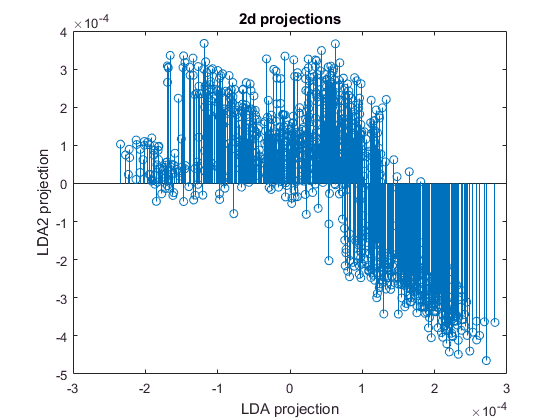

stem(Xnew10(:,1),Xnew10(:,2))
title('2d projections')
xlabel('LDA projection')
ylabel('LDA2 projection')

## NCA

[Xnew11, mapping] = nca(images4, labels4, 2, 0);

Iteration 1 of 1...


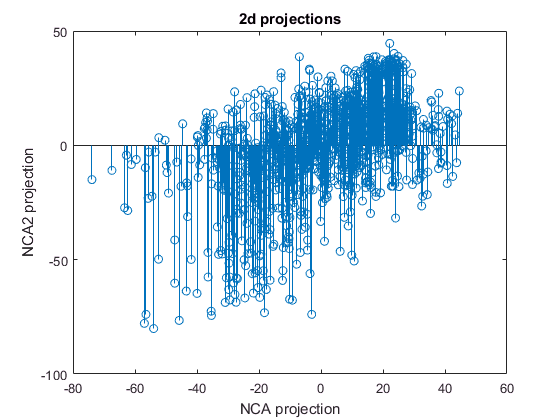

stem(Xnew11(:,1),Xnew11(:,2))
title('2d projections')
xlabel('NCA projection')
ylabel('NCA2 projection')

## Scatterplots

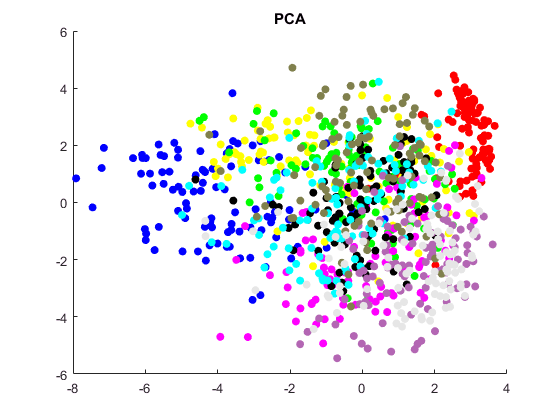

%plotting PCA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew9(1:100,:);
XnewP2=Xnew9(101:200,:);
XnewP3=Xnew9(201:300,:);
XnewP4=Xnew9(301:400,:);
XnewP5=Xnew9(401:500,:);
XnewP6=Xnew9(501:600,:);
XnewP7=Xnew9(601:700,:);
XnewP8=Xnew9(701:800,:);
XnewP9=Xnew9(801:900,:);
XnewP10=Xnew9(901:1000,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('PCA')
hold off

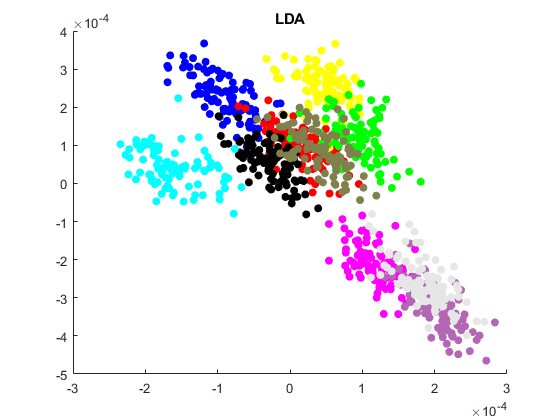

%plotting LDA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew10(1:100,:);
XnewP2=Xnew10(101:200,:);
XnewP3=Xnew10(201:300,:);
XnewP4=Xnew10(301:400,:);
XnewP5=Xnew10(401:500,:);
XnewP6=Xnew10(501:600,:);
XnewP7=Xnew10(601:700,:);
XnewP8=Xnew10(701:800,:);
XnewP9=Xnew10(801:900,:);
XnewP10=Xnew10(901:1000,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('LDA')
hold off

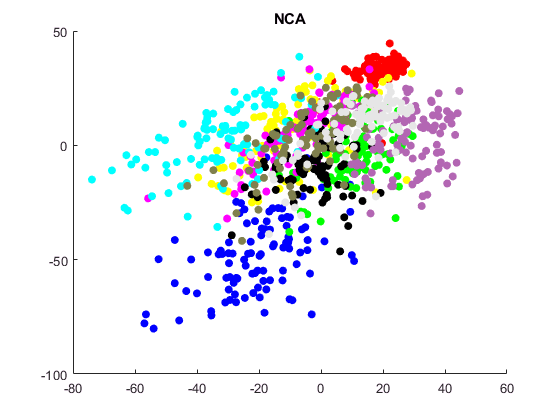

%plotting NCA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew11(1:100,:);
XnewP2=Xnew11(101:200,:);
XnewP3=Xnew11(201:300,:);
XnewP4=Xnew11(301:400,:);
XnewP5=Xnew11(401:500,:);
XnewP6=Xnew11(501:600,:);
XnewP7=Xnew11(601:700,:);
XnewP8=Xnew11(701:800,:);
XnewP9=Xnew11(801:900,:);
XnewP10=Xnew11(901:1000,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('NCA')
hold off

# Scatter Matrix

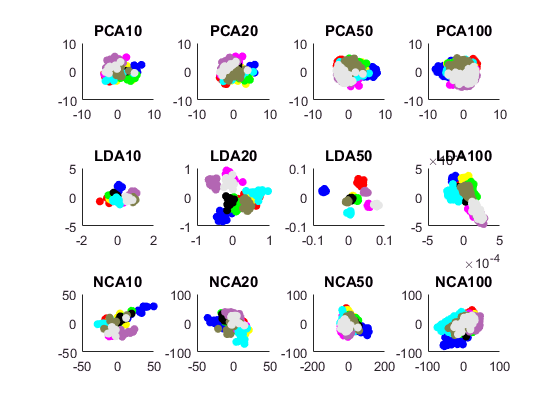

subplot(3,4,1)
%plotting PCA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew(1:10,:);
XnewP2=Xnew(11:20,:);
XnewP3=Xnew(21:30,:);
XnewP4=Xnew(31:40,:);
XnewP5=Xnew(41:50,:);
XnewP6=Xnew(51:60,:);
XnewP7=Xnew(61:70,:);
XnewP8=Xnew(71:80,:);
XnewP9=Xnew(81:90,:);
XnewP10=Xnew(91:100,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('PCA10')
hold off
subplot(3,4,2)
%plotting PCA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew3(1:20,:);
XnewP2=Xnew3(21:40,:);
XnewP3=Xnew3(41:60,:);
XnewP4=Xnew3(61:80,:);
XnewP5=Xnew3(81:100,:);
XnewP6=Xnew3(101:120,:);
XnewP7=Xnew3(121:140,:);
XnewP8=Xnew3(141:160,:);
XnewP9=Xnew3(161:180,:);
XnewP10=Xnew3(181:200,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('PCA20')
hold off
subplot(3,4,3)
%plotting PCA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew6(1:50,:);
XnewP2=Xnew6(51:100,:);
XnewP3=Xnew6(101:150,:);
XnewP4=Xnew6(151:200,:);
XnewP5=Xnew6(201:250,:);
XnewP6=Xnew6(251:300,:);
XnewP7=Xnew6(301:350,:);
XnewP8=Xnew6(351:400,:);
XnewP9=Xnew6(401:450,:);
XnewP10=Xnew6(451:500,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('PCA50')
hold off
subplot(3,4,4)
%plotting PCA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew9(1:100,:);
XnewP2=Xnew9(101:200,:);
XnewP3=Xnew9(201:300,:);
XnewP4=Xnew9(301:400,:);
XnewP5=Xnew9(401:500,:);
XnewP6=Xnew9(501:600,:);
XnewP7=Xnew9(601:700,:);
XnewP8=Xnew9(701:800,:);
XnewP9=Xnew9(801:900,:);
XnewP10=Xnew9(901:1000,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('PCA100')
hold off
subplot(3,4,5)
%plotting LDA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew1(1:10,:);
XnewP2=Xnew1(11:20,:);
XnewP3=Xnew1(21:30,:);
XnewP4=Xnew1(31:40,:);
XnewP5=Xnew1(41:50,:);
XnewP6=Xnew1(51:60,:);
XnewP7=Xnew1(61:70,:);
XnewP8=Xnew1(71:80,:);
XnewP9=Xnew1(81:90,:);
XnewP10=Xnew1(91:100,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('LDA10')
hold off
subplot(3,4,6)
%plotting LDA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew4(1:20,:);
XnewP2=Xnew4(21:40,:);
XnewP3=Xnew4(41:60,:);
XnewP4=Xnew4(61:80,:);
XnewP5=Xnew4(81:100,:);
XnewP6=Xnew4(101:120,:);
XnewP7=Xnew4(121:140,:);
XnewP8=Xnew4(141:160,:);
XnewP9=Xnew4(161:180,:);
XnewP10=Xnew4(181:200,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('LDA20')
hold off
subplot(3,4,7)
%plotting LDA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew7(1:50,:);
XnewP2=Xnew7(51:100,:);
XnewP3=Xnew7(101:150,:);
XnewP4=Xnew7(151:200,:);
XnewP5=Xnew7(201:250,:);
XnewP6=Xnew7(251:300,:);
XnewP7=Xnew7(301:350,:);
XnewP8=Xnew7(351:400,:);
XnewP9=Xnew7(401:450,:);
XnewP10=Xnew7(451:500,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('LDA50')
hold off
subplot(3,4,8)
%plotting LDA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew10(1:100,:);
XnewP2=Xnew10(101:200,:);
XnewP3=Xnew10(201:300,:);
XnewP4=Xnew10(301:400,:);
XnewP5=Xnew10(401:500,:);
XnewP6=Xnew10(501:600,:);
XnewP7=Xnew10(601:700,:);
XnewP8=Xnew10(701:800,:);
XnewP9=Xnew10(801:900,:);
XnewP10=Xnew10(901:1000,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('LDA100')
hold off
subplot(3,4,9)
%plotting NCA
color1=[0,0.4470, 0.7410];
XnewP1=mappedX(1:10,:);
XnewP2=mappedX(11:20,:);
XnewP3=mappedX(21:30,:);
XnewP4=mappedX(31:40,:);
XnewP5=mappedX(41:50,:);
XnewP6=mappedX(51:60,:);
XnewP7=mappedX(61:70,:);
XnewP8=mappedX(71:80,:);
XnewP9=mappedX(81:90,:);
XnewP10=mappedX(91:100,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('NCA10')
hold off
subplot(3,4,10)
%plotting NCA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew5(1:20,:);
XnewP2=Xnew5(21:40,:);
XnewP3=Xnew5(41:60,:);
XnewP4=Xnew5(61:80,:);
XnewP5=Xnew5(81:100,:);
XnewP6=Xnew5(101:120,:);
XnewP7=Xnew5(121:140,:);
XnewP8=Xnew5(141:160,:);
XnewP9=Xnew5(161:180,:);
XnewP10=Xnew5(181:200,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('NCA20')
hold off
subplot(3,4,11)
%plotting NCA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew8(1:50,:);
XnewP2=Xnew8(51:100,:);
XnewP3=Xnew8(101:150,:);
XnewP4=Xnew8(151:200,:);
XnewP5=Xnew8(201:250,:);
XnewP6=Xnew8(251:300,:);
XnewP7=Xnew8(301:350,:);
XnewP8=Xnew8(351:400,:);
XnewP9=Xnew8(401:450,:);
XnewP10=Xnew8(451:500,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('NCA50')
hold off
subplot(3,4,12)
%plotting NCA
color1=[0,0.4470, 0.7410];
XnewP1=Xnew11(1:100,:);
XnewP2=Xnew11(101:200,:);
XnewP3=Xnew11(201:300,:);
XnewP4=Xnew11(301:400,:);
XnewP5=Xnew11(401:500,:);
XnewP6=Xnew11(501:600,:);
XnewP7=Xnew11(601:700,:);
XnewP8=Xnew11(701:800,:);
XnewP9=Xnew11(801:900,:);
XnewP10=Xnew11(901:1000,:);
scatter(XnewP1(:,1),XnewP1(:,2),'filled','b')
hold on
scatter(XnewP2(:,1),XnewP2(:,2),'filled','r')
hold on
scatter(XnewP3(:,1),XnewP3(:,2),'filled','y')
hold on
scatter(XnewP4(:,1),XnewP4(:,2),'filled','g')
hold on
scatter(XnewP5(:,1),XnewP5(:,2),'filled','m')
hold on
scatter(XnewP6(:,1),XnewP6(:,2),'filled','k')
hold on
scatter(XnewP7(:,1),XnewP7(:,2),'filled','c')
hold on
scatter(XnewP8(:,1),XnewP8(:,2),'filled','MarkerFaceColor',[0.7,0.4,0.7])
hold on
scatter(XnewP9(:,1),XnewP9(:,2),'filled','MarkerFaceColor',[0.5,0.5,0.3])
hold on
scatter(XnewP10(:,1),XnewP10(:,2),'filled','MarkerFaceColor',[0.9,0.9,0.9])
title('NCA100')
hold off

# Conclusion

## The NCA and LDA algorithms show significantly better clustering as compared to the PCA algorithm. LDA shows best clustering at 50. NCA shows best clustering at 100. Overall as the number of samples increase the clustering results get progressively better. The NCA algorithm however might have a problem since it should show better results than the LDA algorithm however it does not do that in theory NCA > LDA>PCA however that is not observed here in this case LDA is the best.

function [Y] = LDA(X, L)

    Classes=unique(L)';
    k=numel(Classes);

    n=zeros(k,1);
    C=cell(k,1);
    M=mean(X);
    S=cell(k,1);
    Sw=0;
    Sb=0;
    for j=1:k
        Xj=X(L==Classes(j),:);
        n(j)=size(Xj,1);
        C{j}=mean(Xj);
        S{j}=0;
        for i=1:n(j)
            S{j}=S{j}+(Xj(i,:)-C{j})'*(Xj(i,:)-C{j});
        end
        Sw=Sw+S{j};
        Sb=Sb+n(j)*(C{j}-M)'*(C{j}-M);
    end

    [u, v, d]=svd((pinv(Sw) * Sb));

    %lambda=diag(LAMBDA);

    %[lambda, SortOrder]=sort(lambda,'descend');

    %W=W(:,SortOrder);
    
    u=u(:,1:2);
    
    Y=X*u;

end
function [mappedX, mapping] = nca(X, labels, no_dims, lambda)
%NCA Performs NCA on the specified dataset
%
%   [mappedX, mapping] = nca(X, labels, no_dims, lambda)
%
% Performs linear Neighborhood Components Analysis (NCA) on the 
% dataset specified through X and labels to reduce the data dimensionality 
% to no_dims dimensions. If valid_X and valid_labels are specified, the
% function uses early stopping based on NN errors.
% The function returns a embedded data in mappedX, as well as th mapping.
%
%

% This file is part of the Matlab Toolbox for Dimensionality Reduction.
% The toolbox can be obtained from http://homepage.tudelft.nl/19j49
% You are free to use, change, or redistribute this code in any way you
% want for non-commercial purposes. However, it is appreciated if you 
% maintain the name of the original author.
%
% (C) Laurens van der Maaten, Delft University of Technology



    if ~exist('no_dims', 'var') || isempty(no_dims)
        no_dims = size(X, 2);
    end
    if ~exist('lambda', 'var') || isempty(lambda)
        lambda = 0;
    end
    
    % Make sure data is zero mean
    mapping.mean = mean(X, 1);
	X = bsxfun(@minus, X, mapping.mean);

    % Initialize some variables
    max_iter = 200;
    [n, d] = size(X);
    batch_size = min(5000, n);
    no_batches = ceil(n / batch_size);
    max_iter = ceil(max_iter / no_batches);
    [lablist, foo, labels] = unique(labels);
    A = randn(d, no_dims) * .01;
    converged = false;
    iter = 0;
    
    % Main iteration loop
    while iter < max_iter && ~converged
        
        % Loop over batches
        iter = iter + 1;
        disp(['Iteration ' num2str(iter) ' of ' num2str(max_iter) '...']);
        ind = randperm(n);
        for batch=1:batch_size:n
    
            % Run NCA minimization using three linesearches
            cur_X    = double(X(ind(batch:min([batch + batch_size - 1 n])),:));
            cur_labels = labels(ind(batch:min([batch + batch_size - 1 n])));
            [A, f] = minimize(A(:), 'nca_lin_grad', 5, cur_X, cur_labels, no_dims, lambda);
            A = reshape(A, [d no_dims]);
            if isempty(f) || f(end) - f(1) > -1e-4
                disp('Converged!');
                converged = true;
            end
        end
    end
    
    % Compute embedding
    mapping.M = A;
    mappedX = X * mapping.M;
end
function [F, dF] = nca_lin_grad(x, X, labels, no_dims, lambda)
%NCA_LIN_GRAD Computes NCA gradient on the specified dataset
%
%   [C, dC] = nca_lin_grad(x, X, labels, no_dims, lambda)
%
% Computes the linear Neighborhood Components Analysis (NCA) gradient 
% on the dataset specified through X and labels to reduce the data 
% dimensionality to no_dims dimensions. The current solutions is specified 
% in x. The function returns the current value of the cost function in C 
% and the gradient in dC.
%
%

% This file is part of the Matlab Toolbox for Dimensionality Reduction.
% The toolbox can be obtained from http://homepage.tudelft.nl/19j49
% You are free to use, change, or redistribute this code in any way you
% want for non-commercial purposes. However, it is appreciated if you 
% maintain the name of the original author.
%
% (C) Laurens van der Maaten, Delft University of Technology

    
    if ~exist('lambda', 'var') || isempty(lambda)
        lambda = 0;
    end

    % Initialize some variables
    n = size(X, 1);
    A = reshape(x, [numel(x) / no_dims no_dims]);
    F = 0;
    dF = zeros(size(A));

    % Transform the data
    Y = X * A;
    
    % Compute conditional probabilities for current solution
    sumY = sum(Y .^ 2, 2);
    P = exp(bsxfun(@minus, bsxfun(@minus, 2 * (Y * Y'), sumY'), sumY));
    P(1:n+1:end) = 0;
    P = bsxfun(@rdivide, P, sum(P, 2));
    P = max(P, eps);

    % Compute value of cost function and gradient
    for i=1:n
        
        % Sum cost function
        inds = (labels == labels(i));
        Pi = sum(P(i, inds));
        F = F + Pi;

        % Sum gradient
        if nargout > 1
            xikA = bsxfun(@minus, Y(i,:), Y);
            xik  = bsxfun(@minus, X(i,:), X);
            dF = dF + Pi * (bsxfun(@times, xik,         P(i,:)')'     * xikA) - ...
                            bsxfun(@times, xik(inds,:), P(i, inds)')' * xikA(inds,:);
        end
    end
    
    % Include regularization term
    F = F - lambda .* sum(A(:) .^ 2) ./ numel(A);
    dF = 2 * dF - 2 * lambda .* A ./ numel(A);

    % Prepare to pass to minimize
    F = -F;
    dF = -dF(:);
end
function [X, fX, i] = minimize(X, f, length, P1, P2, P3, P4, P5, P6);

% Minimize a continuous differentialble multivariate function. Starting point
% is given by "X" (D by 1), and the function named in the string "f", must
% return a function value and a vector of partial derivatives. The Polack-
% Ribiere flavour of conjugate gradients is used to compute search directions,
% and a line search using quadratic and cubic polynomial approximations and the
% Wolfe-Powell stopping criteria is used together with the slope ratio method
% for guessing initial step sizes. Additionally a bunch of checks are made to
% make sure that exploration is taking place and that extrapolation will not
% be unboundedly large. The "length" gives the length of the run: if it is
% positive, it gives the maximum number of line searches, if negative its
% absolute gives the maximum allowed number of function evaluations. You can
% (optionally) give "length" a second component, which will indicate the
% reduction in function value to be expected in the first line-search (defaults
% to 1.0). The function returns when either its length is up, or if no further
% progress can be made (ie, we are at a minimum, or so close that due to
% numerical problems, we cannot get any closer). If the function terminates
% within a few iterations, it could be an indication that the function value
% and derivatives are not consistent (ie, there may be a bug in the
% implementation of your "f" function). The function returns the found
% solution "X", a vector of function values "fX" indicating the progress made
% and "i" the number of iterations (line searches or function evaluations,
% depending on the sign of "length") used.
%
% Usage: [X, fX, i] = minimize(X, f, length, P1, P2, P3, P4, P5, P6)
%
% See also: checkgrad 
%
% Copyright (C) 2001 and 2002 by Carl Edward Rasmussen. Date 2002-02-13
%
%

% This file is part of the Matlab Toolbox for Dimensionality Reduction.
% The toolbox can be obtained from http://homepage.tudelft.nl/19j49
% You are free to use, change, or redistribute this code in any way you
% want for non-commercial purposes. However, it is appreciated if you 
% maintain the name of the original author.
%
% (C) Laurens van der Maaten, Delft University of Technology


RHO = 0.01;                            % a bunch of constants for line searches
SIG = 0.5;       % RHO and SIG are the constants in the Wolfe-Powell conditions
INT = 0.1;    % don't reevaluate within 0.1 of the limit of the current bracket
EXT = 3.0;                    % extrapolate maximum 3 times the current bracket
MAX = 20;                         % max 20 function evaluations per line search
RATIO = 100;                                      % maximum allowed slope ratio

argstr = [f, '(X'];                      % compose string used to call function
for i = 1:(nargin - 3)
  argstr = [argstr, ',P', int2str(i)];
end
argstr = [argstr, ')'];

if max(size(length)) == 2, red=length(2); length=length(1); else red=1; end
if length>0, S=['Linesearch']; else S=['Function evaluation']; end 

i = 0;                                            % zero the run length counter
ls_failed = 0;                             % no previous line search has failed
fX = [];
[f1 df1] = eval(argstr);                      % get function value and gradient
i = i + (length<0);                                            % count epochs?!
s = -df1;                                        % search direction is steepest
d1 = -s'*s;                                                 % this is the slope
z1 = red/(1-d1);                                  % initial step is red/(|s|+1)

while i < abs(length)                                      % while not finished
  i = i + (length>0);                                      % count iterations?!

  X0 = X; f0 = f1; df0 = df1;                   % make a copy of current values
  X = X + z1*s;                                             % begin line search
  [f2 df2] = eval(argstr);
  i = i + (length<0);                                          % count epochs?!
  d2 = df2'*s;
  f3 = f1; d3 = d1; z3 = -z1;             % initialize point 3 equal to point 1
  if length>0, M = MAX; else M = min(MAX, -length-i); end
  success = 0; limit = -1;                     % initialize quanteties
  while 1
    while ((f2 > f1+z1*RHO*d1) | (d2 > -SIG*d1)) & (M > 0) 
      limit = z1;                                         % tighten the bracket
      if f2 > f1
        z2 = z3 - (0.5*d3*z3*z3)/(d3*z3+f2-f3);                 % quadratic fit
      else
        A = 6*(f2-f3)/z3+3*(d2+d3);                                 % cubic fit
        B = 3*(f3-f2)-z3*(d3+2*d2);
        z2 = (sqrt(B*B-A*d2*z3*z3)-B)/A;       % numerical error possible - ok!
      end
      if isnan(z2) | isinf(z2)
        z2 = z3/2;                  % if we had a numerical problem then bisect
      end
      z2 = max(min(z2, INT*z3),(1-INT)*z3);  % don't accept too close to limits
      z1 = z1 + z2;                                           % update the step
      X = X + z2*s;
      [f2 df2] = eval(argstr);
      M = M - 1; i = i + (length<0);                           % count epochs?!
      d2 = df2'*s;
      z3 = z3-z2;                    % z3 is now relative to the location of z2
    end
    if f2 > f1+z1*RHO*d1 | d2 > -SIG*d1
      break;                                                % this is a failure
    elseif d2 > SIG*d1
      success = 1; break;                                             % success
    elseif M == 0
      break;                                                          % failure
    end
    A = 6*(f2-f3)/z3+3*(d2+d3);                      % make cubic extrapolation
    B = 3*(f3-f2)-z3*(d3+2*d2);
    z2 = -d2*z3*z3/(B+sqrt(B*B-A*d2*z3*z3));        % num. error possible - ok!
    if ~isreal(z2) | isnan(z2) | isinf(z2) | z2 < 0   % num prob or wrong sign?
      if limit < -0.5                               % if we have no upper limit
        z2 = z1 * (EXT-1);                 % the extrapolate the maximum amount
      else
        z2 = (limit-z1)/2;                                   % otherwise bisect
      end
    elseif (limit > -0.5) & (z2+z1 > limit)          % extraplation beyond max?
      z2 = (limit-z1)/2;                                               % bisect
    elseif (limit < -0.5) & (z2+z1 > z1*EXT)       % extrapolation beyond limit
      z2 = z1*(EXT-1.0);                           % set to extrapolation limit
    elseif z2 < -z3*INT
      z2 = -z3*INT;
    elseif (limit > -0.5) & (z2 < (limit-z1)*(1.0-INT))   % too close to limit?
      z2 = (limit-z1)*(1.0-INT);
    end
    f3 = f2; d3 = d2; z3 = -z2;                  % set point 3 equal to point 2
    z1 = z1 + z2; X = X + z2*s;                      % update current estimates
    [f2 df2] = eval(argstr);
    M = M - 1; i = i + (length<0);                             % count epochs?!
    d2 = df2'*s;
  end                                                      % end of line search

  if success                                         % if line search succeeded
    f1 = f2; fX = [fX' f1]';
%     fprintf('%s %6i;  Value %4.6e\r', S, i, f1);
    s = (df2'*df2-df1'*df2)/(df1'*df1)*s - df2;      % Polack-Ribiere direction
    tmp = df1; df1 = df2; df2 = tmp;                         % swap derivatives
    d2 = df1'*s;
    if d2 > 0                                      % new slope must be negative
      s = -df1;                              % otherwise use steepest direction
      d2 = -s'*s;    
    end
    z1 = z1 * min(RATIO, d1/(d2-realmin));          % slope ratio but max RATIO
    d1 = d2;
    ls_failed = 0;                              % this line search did not fail
  else
    X = X0; f1 = f0; df1 = df0;  % restore point from before failed line search
    if ls_failed | i > abs(length)          % line search failed twice in a row
      break;                             % or we ran out of time, so we give up
    end
    tmp = df1; df1 = df2; df2 = tmp;                         % swap derivatives
    s = -df1;                                                    % try steepest
    d1 = -s'*s;
    z1 = 1/(1-d1);                     
    ls_failed = 1;                                    % this line search failed
  end
end
end